clear
% Define the folder path
folderPath = 'HDR/JPG'; % Adjust the path as necessary
%folderPath = 'images'; % Adjust the path as necessary

% Create an imageDatastore for all JPG files in the folder
imds = imageDatastore(folderPath, 'FileExtensions', '.JPG');
%imds = imageDatastore(folderPath, 'FileExtensions', '.jfif');

% Display the number of images found
numImages = numel(imds.Files);
disp(['Number of JPG images found: ', num2str(numImages)]);

Number of JPG images found: 14


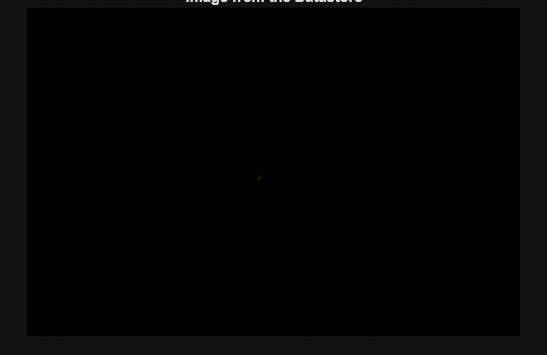


% Read the i-th image from the datastore
img = readimage(imds, 1);

% Display the image
imshow(img);
title('Image from the Datastore');

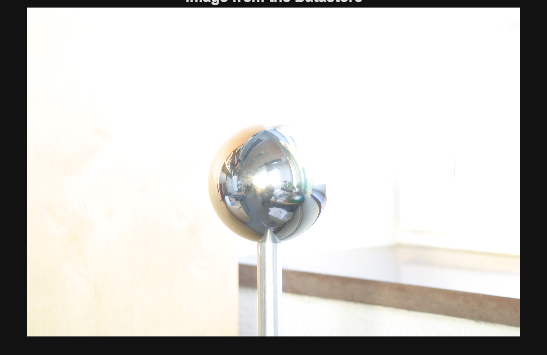

img = readimage(imds, numImages);
imshow(img);
title('Image from the Datastore');





%Ranom Sampling of pixels
[H, W, C] = size(img); % read image Height, Width, Channel. Assumed same for all images duuh

numSamples = 200;
rng(0);
% meshgrid avoids sample clustering. grid bias + random.
[Xs, Ys] = meshgrid(round(linspace(1,W,round(sqrt(numSamples)))), round(linspace(1,H,sqrt(numSamples))));
coord = [Xs(:),Ys(:)];
if size(coord, 1) < numSamples
    extra = numSamples - size(coord,1);
    randCoord = [randi(W, extra, 1), randi(H, extra, 1)];
    coord = [coord; randCoord];
else
    coord = coord(1:numSamples,:);
end
% I orginal artikeln så nämns det att de kastade även ut väldigt saturerade
% värden dvs 255


exposureTimes = zeros(numImages,1);
for j = 1:numImages
    info = imfinfo(imds.Files{j});
    exposureTimes(j) = info.DigitalCamera.ExposureTime;
end

B = log(exposureTimes);

% Hat weight 
Zmin = 0;
Zmax = 255;
Zmid = Zmax/2;
wvec = zeros(256, 1);
for z = Zmin:Zmax
    if z <= Zmid
        wvec(z+1) = z - Zmin;
    else
        wvec(z+1) = Zmax -z;
    end
end



% Read camera curve, named gfun
load("HDR\gfun.mat")



% Sample pixel values for each channel separately
Z_red = zeros(numSamples, numImages);
Z_green = zeros(numSamples, numImages);
Z_blue = zeros(numSamples, numImages);

for j = 1:numImages
    Ij = im2double(readimage(imds, j));
    Ij = rgb2lin(Ij);
    for i = 1:numSamples
        for ch = 1:3
        Z_red(i,j) = round(Ij(coord(i,2), coord(i,1), 1) * 255);
        Z_green(i,j) = round(Ij(coord(i,2), coord(i,1), 2) * 255);
        Z_blue(i,j) = round(Ij(coord(i,2), coord(i,1), 3) * 255);
        end
    end
end

lambda = 1;
[g_red, lE_red] = gsolve(Z_red, B, lambda, wvec);
[g_green, lE_green] = gsolve(Z_green, B, lambda, wvec);
[g_blue, lE_blue] = gsolve(Z_blue, B, lambda, wvec);

% Combine into a singular g
g = {g_red, g_green, g_blue};





%Load all images (now with colour)
for j = 1:numImages

    Ij = im2double(imread(imds.Files{j}));
    Ij = rgb2lin(Ij); %sRGB to linear RGB behövs för korrekt algo
    %No CIELAB should be used because the algoritim needs accurate
    %radiometric values

    if j == 1 
        [H,W,C] = size(Ij);
        images = zeros(H,W,C,numImages);

    end 
    images(:,:,:,j) = Ij;
end 


%reconstruct image in .hdr (Radiance) 
lnE = zeros(H,W,C);

for ch = 1:C
    for y = 1:H
        for x = 1:W
            num = 0;
            den = 0;
            for j = 1:numImages
                % Pixel value in [0,255] for channel ch
                z = round(images(y,x,ch,j) * 255);

                % Clamp
                z = max(0, min(255, z));

                wij = wvec(z+1);
                num = num + wij * (g{ch}(z+1) - B(j));  % g per channel
                den = den + wij;
            end

            if den > 0
                lnE(y,x,ch) = num / den;
            else
                lnE(y,x,ch) = 0;
            end
        end
    end
end

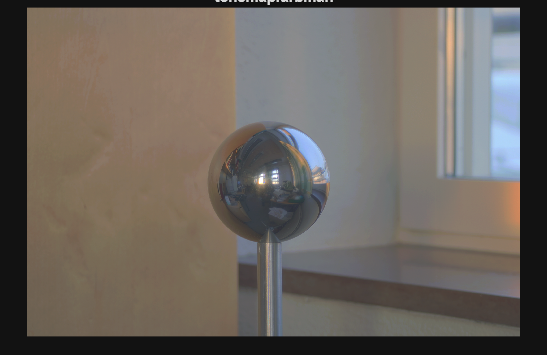


% vad ska vi göra med kameran btw?
HDR = exp(lnE);
%HDR3 = repmat(HDR, [1, 1, 3])
hdrwrite(single(HDR), 'result.hdr'); 
%Result blir nästan helt vit när man kollar i photoshop
% hade dock inte hdr-läge på men men. 

% Nu använder den:
% edge-preserving decompositions for multiscale tone and detail manipulation
% tonemap men vi ska göra egen eller något sånt. 
LDR_final = tonemapfarbman(HDR, 'Exposure', 0.5);
%LDR_final = tonemapfarbman(HDR);
imshow(LDR_final)
title('tonemapfarbman')

% This section is from the paper 
% HDR-Debevec-97.pdf


% gsolve.m − Solve for imaging system response function
%
% Given a set of pixel values observed for several pixels in several
% images with different exposure times, this function returns the
% imaging system’s response function g as well as the log film irradiance
% values for the observed pixels.
%
% Assumes:
%
% Zmin = 0
% Zmax = 255
%
% Arguments:
%
% Z(i,j) is the pixel values of pixel location number i in image j
% B(j) is the log delta t, or log shutter speed, for image j
% l is lamdba, the constant that determines the amount of smoothness
% w(z) is the weighting function value for pixel value z
% 
% Returns:
%
% g(z) is the log exposure corresponding to pixel value z
% lE(i) is the log film irradiance at pixel location i
%

function [g,lE]=gsolve(Z,B,l,w)
    n = 256;
    A = zeros(size(Z,1)*size(Z,2)+n+1,n+size(Z,1));
    b = zeros(size(A,1),1);
    %% Include the data−fitting equations
    k = 1;
    for i=1:size(Z,1)
        for j=1:size(Z,2)
            wij = w(Z(i,j)+1);
            A(k,Z(i,j)+1) = wij; 
            A(k,n+i) = -wij; 
            b(k,1) = wij * B(j);
            k=k+1;
        end
    end
    %% Fix the curve by setting its middle value to 0
    A(k,129) = 1;
    k=k+1;
    %% Include the smoothness equations
    for i=1:n-2
     A(k,i)=l*w(i+1); A(k,i+1)=-2*l*w(i+1); A(k,i+2)=l*w(i+1);
     k=k+1;
    end
    %% Solve the system using SVD
    x = A\b;
    g = x(1:n);
    lE = x(n+1:size(x,1));
end
